# **Structural Optimization**

## **Exercise 3.3**

One wants to minimize the weight of the two-bar truss in Fig. 3.10. The lengths are 5L and 3L, respectively. Young’s modulus is E and the density is ρ for both bars, and the force P>0. The design variables are the cross-sectional areas of the bars: $A_{1\;}$ and $A_2$. The truss has to be sufficiently stiff; more precisely, the so - called compliance has to be lower than a specified number:


$$-P \cdot u_x -P \cdot u_ y \leq C_0$$


where($u_x$,$u_{y\;}$) are the displacements of the free node,and $C_0$  is a given number.

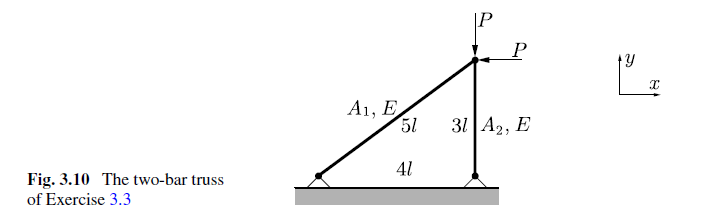

- Formulate the problem as a mathematical programming problem.

- Change variables to nondimensional ones as xi = P/(EAi), i = 1, 2, and solve the optimization problem by using the KKT conditions.

- Same as 2), but solve the optimization problem by using Lagrangian duality instead.

### **Answer:**

Since we want to minimize the weight of the truss, the objective function of the truss will be the sum of the weights of the two trusses. We write the objective function in $x_{1\;}$and $x_2$. It can be written as follows:

syms P E L x1 x2 rho A1 A2 delta1 delta2 Co lambda real positive

x_1=x1==P/(E*A1)

$$x\_1 = x_{1}=\frac{P}{A_{1}\,\text{E}}$$

x_2=x2==P/(E*A2)

$$x\_2 = x_{2}=\frac{P}{A_{2}\,\text{E}}$$

A1=solve(x_1,A1)

$$A1 = \frac{P}{\text{E}\,x_{1}}$$

A2=solve(x_2,A2)

$$A2 = \frac{P}{\text{E}\,x_{2}}$$

The objective function is $f(A_1,A_2)=\rho \cdot L(5A_1+3A_2)$ can then be written in $x_{1\;}$and $x_2$ as:

f=rho*L*(5*A1+3*A2)

$$f = L\,\rho \,\left(\frac{5\,P}{\text{E}\,x_{1}}+\frac{3\,P}{\text{E}\,x_{2}}\right)$$

Since the $\rho ,L,\;P,\;E$ is constant, then the objective function can be written in $x_{1\;}$and $x_2$ terms as $g_0 \left(x_{1,} x_2 \right)$

g0=expand(simplify(f/(L*rho*P)*E))

$$g0 = \frac{5}{x_{1}}+\frac{3}{x_{2}}$$

The constraint need to be evaluated from the $\delta \;$ relation with $u$. It is also need to be evaluated from the relationship of $s$ and $P$ and  It is know that ${\sigma \;}_i =\frac{s_i }{A_i }$ and $\varepsilon_{i\;} =\frac{\delta {\;}_i }{L_i }$. Therefore, from Hooke's law, ${\sigma \;}_i =E\cdot \varepsilon {\;}_{i\;}$, the $\delta {\;}_{i\;} =\frac{s_{i\;} \cdot L_i }{E\cdot \;A_i }$. 

where,

$\left[\matrix{ F_x \cr F_y} \right]=\left[\matrix{-sin\theta&0 \cr -cos\theta& -1}\right]\left[\matrix{s_1\cr s_2}\right]$; $\left[\matrix{ F_x \cr F_y} \right]=\left[\matrix{-P\cr -P}\right]$

and


$$\left[\matrix{ \delta_1 \cr \delta_2} \right]=\left[\matrix{-sin\theta&-cos\theta \cr -0& -1}\right]\left[\matrix{u_x\cr u_y}\right]$$


***Subscripts 1 and 2 are corresponded to element/truss 1 and 2, while subscripts x and y are corresponded to direction x and y.***

F=[-P;-P];
L1=5*L;
L2=3*L;
s=[delta1*E*A1/L1;delta2*E*A2/L2];


theta=atan(4/3);

B=[-sin(theta) -cos(theta); 0 -1]

B =    -0.8000   -0.6000
         0   -1.0000


BT=transpose(B);
ForceEqn=F==BT*s;
[delta1,delta2]=solve(ForceEqn,[delta1,delta2])

$$delta1 = \frac{25\,L\,x_{1}}{4}$$

$$delta2 = \frac{3\,L\,x_{2}}{4}$$

Insert this to the definition of $\delta$, we could obtain $u$ as:

u=B\[delta1;delta2]

$$u = \left(\begin{array}{c} \frac{9\,L\,x_{2}}{16}-\frac{125\,L\,x_{1}}{16}\\ -\frac{3\,L\,x_{2}}{4} \end{array}\right)$$

g1=(simplify(transpose(F)*u-Co))

$$g1 = \frac{125\,L\,P\,x_{1}}{16}-\mathrm{Co}+\frac{3\,L\,P\,x_{2}}{16}$$

#### **KKT Condition Calculation**

L=g0+lambda*g1;
lambdag1=lambda*g1

$$lambdag1 = \lambda \,\left(\frac{125\,L\,P\,x_{1}}{16}-\mathrm{Co}+\frac{3\,L\,P\,x_{2}}{16}\right)$$


dL_dx1=diff(L,x1)

$$dL\_dx1 = \frac{125\,L\,P\,\lambda }{16}-\frac{5}{{x_{1}}^{2}}$$

dL_dx2=diff(L,x2)

$$dL\_dx2 = \frac{3\,L\,P\,\lambda }{16}-\frac{3}{{x_{2}}^{2}}$$

KKTMat=[lambdag1;dL_dx1;dL_dx2]==[0;0;0];
sol=solve([KKTMat(1),KKTMat(2),KKTMat(3)],[x1,x2,lambda])

sol = struct with fields:
        x1: (4*Co)/(35*L*P)
        x2: (4*Co)/(7*L*P)
    lambda: (49*L*P)/Co^2


syms As1 As2
A_1=(P/(As1*E))==sol.x1;
A_2=(P/(As2*E))==sol.x2;

A_solved1=solve(A_1,As1)

$$A\_solved1 = \frac{35\,L\,P^{2}}{4\,\mathrm{Co}\,\text{E}}$$

A_solved2=solve(A_2,As2)

$$A\_solved2 = \frac{7\,L\,P^{2}}{4\,\mathrm{Co}\,\text{E}}$$

#### Langangian Duality

Since the Lagrangian and its derivatives on $x_1$ and $x_2$ have been acquired, the next step is to solve $x_1$ and $x_2$ for the derivatives are equal to zero.

xL_1=dL_dx1==0;
xL_2=dL_dx2==0;

xL1=solve(xL_1,x1)

$$xL1 = \frac{4}{5\,\sqrt{L}\,\sqrt{P}\,\sqrt{\lambda }}$$

xL2=solve(xL_2,x2)

$$xL2 = \frac{4}{\sqrt{L}\,\sqrt{P}\,\sqrt{\lambda }}$$

L_duality=simplify(subs(L,[x1,x2],[xL1,xL2]))

$$L\_duality = 14\,\sqrt{L}\,\sqrt{P}\,\sqrt{\lambda }-\mathrm{Co}\,\lambda$$

dL_duality=diff(L_duality,lambda)

$$dL\_duality = \frac{7\,\sqrt{L}\,\sqrt{P}}{\sqrt{\lambda }}-\mathrm{Co}$$

lambda_eqn=dL_duality==0;
lambda_s=solve(lambda_eqn,lambda)

$$lambda\_s = \frac{49\,L\,P}{{\mathrm{Co}}^{2}}$$

x1_duality=simplify(subs(xL1,lambda,lambda_s))

$$x1\_duality = \frac{4\,\mathrm{Co}}{35\,L\,P}$$

x2_duality=simplify(subs(xL2,lambda,lambda_s))

$$x2\_duality = \frac{4\,\mathrm{Co}}{7\,L\,P}$$

AL_solved1=solve(x1_duality==(P/(As1*E)),As1)

$$AL\_solved1 = \frac{35\,L\,P^{2}}{4\,\mathrm{Co}\,\text{E}}$$

AL_solved2=solve(x2_duality==(P/(As2*E)),As2)

$$AL\_solved2 = \frac{7\,L\,P^{2}}{4\,\mathrm{Co}\,\text{E}}$$

Here it can be seen that **KKT Condition Method** and **Lagrangian Duality Method** give the same results both for A1 and A2.